% main file for computing the basin stability of the simple
% wildtype-Wolbachia model


% Ben Adams, 2024, adpated from Merten Stender
% Hamburg University of Technology, Dynamics Group
% www.tuhh.de/dyn

% m.stender@tuhh.de
%
% 08.01.2021
% -------------------------------------------------------------------------


% NOTE: <init_bStab> must be located on the active Matlab path!


% ensure a clean start
clear; close all; clc;

% define a name for the current analysis (a subdirectory will be created in
% this folder)
currentCase = 'case_1';

% set up paths, initialize bSTAB, create properties struct <props>
[props] = init_bSTAB(currentCase);

## 1. set up your case

all the properties, options and parameters defined hereafter will be assigned to a single struct 'props' that makes the handling easier. You will only need to change this file for your indivudual system (and the functions referenced herein).

[props] = setup_wolbachia(props);

% if you quickly want to update model parameters, you can change them via
% props.model.odeParams = []; here

## 2. compute the basin stability

% let bSTAB compute the basin stability values
[res_tab, res_detail, props] = compute_bs(props);

initial condition sampling strategy: uniform random
0: Starting the PARFOR progress bar failed - probably, you do not have access to the  Instrument Control Toolbox
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
time integration 54/1000
time integration 9/1000
time integration 18/1000
time integration 17/1000
time integration 36/1000
time integration 27/1000
time integration 45/1000
time integration 53/1000
time integration 52/1000
time integration 51/1000
time integration 50/1000
time integration 8/1000
time integration 16/1000
time integration 15/1000
time integration 14/1000
time integration 35/1000
time integration 34/1000
time integration 33/1000
time integration 32/1000
time integration 31/1000
time integration 30/1000
time integration 26/1000
time integration 25/1000
time integration 44/1000
time integration 49/1000
time integration 48/1000
time integration 47/1000
time integration 46/1000
time integration 7/1000
tim


% save the results (the compuatation may have took quite a long time, so
% make sure to not lose the data!)
save([props.subCasePath, '/results_basinstability.mat']);

## 3. plot the results

we provide some basic plotting functionalities. Individual elements must be fine-tuned by the user upon creating final figures (axis labels etc.). This can be done by adding another struct to [props](http://props), and then adapting the plotting functions to take the struct entries and integrate them into the figures.

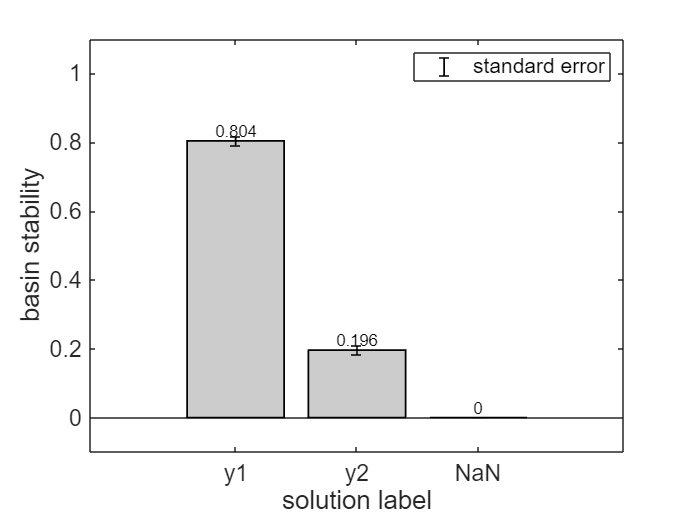

% 1. bar plot for the basin stability values
plot_bs_bargraph(props, res_tab, true);

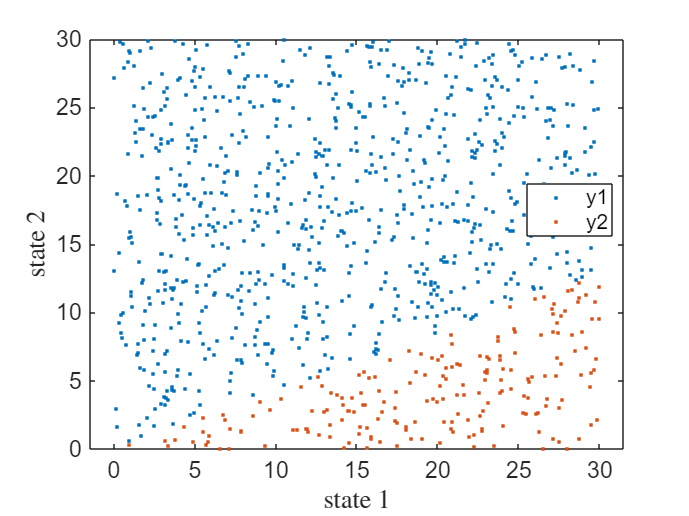


% 2. state space scatter plot: class-labeled initial conditions
plot_bs_statespace(props, res_detail, 1, 2);

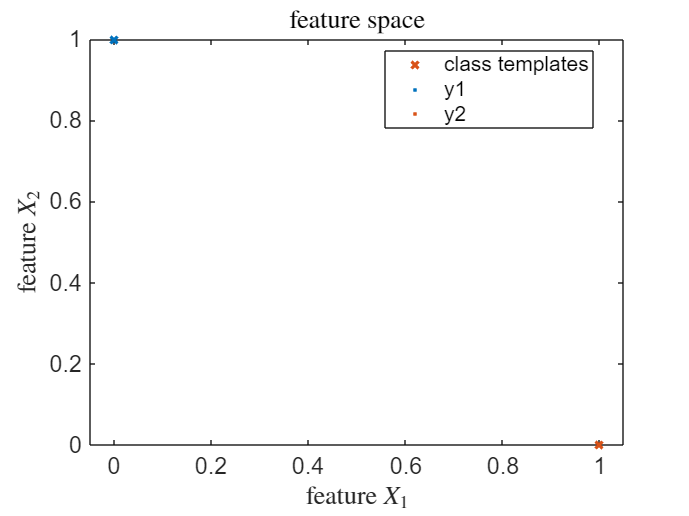


% 3. feature space and classifier results
plot_bs_featurespace(props, res_detail);

## Publication case 1: basin stability at fixed parameters

b = 0.674;
d = 0.12;
d_prime = 0.12;
phi = 0.7;
h = 0.3;
k = 0.76;
C = 30.0;
u = 1.0;
v = 1.0;

tspan = [0, 5000];
options = odeset('RelTol',1e-10);

% M,0 solution
x0 = [8; 0];
[T_m0, Y_m0] = ode45(@(t,y) ode_wolbachia(t, y, b, d, d_prime, phi, h, k, C, u, v), tspan, x0, options);
x0 = [0; 8];
[T_0w, Y_0w] = ode45(@(t,y) ode_wolbachia(t, y, b, d, d_prime, phi, h, k, C, u, v), tspan, x0, options);

% 0,M solution
figure;
plot(T_m0, Y_m0(:,1:2), 'lineWidth', 2); hold on;
plot(T_0w, Y_0w(:,1:2), 'lineWidth', 2);
%set(gca, 'Xtick', [0, 10*pi, 20*pi, 30*pi]);
%set(gca, 'Xticklabel', {'0', '10\pi', '20\pi', '30\pi'});
%set(gca, 'Ytick', [0, 2.5, 0.5/alpha]);
%set(gca, 'Yticklabel', {'0', 'T/2\alpha', 'T/\alpha'});
%ylabel('$y_2$', 'interpreter', 'latex');
%xlabel('time', 'interpreter', 'latex');
%saveas(gcf,[props.subCasePath,'/publication_case1'], 'png');
%savefig(gcf,[props.subCasePath,'/publication_case1']);